% Given Data
V0 = [1.0, 2.0, 3.0, 4.0, 5.0]; % Initial velocities in μM/s
S0 = [20, 50, 100, 200, 500];   % Initial substrate concentrations in mM

% Convert to proper units for calculation
V0 = V0 * 1e-6;   % Convert μM/s to M/s
S0 = S0 * 1e-3;   % Convert mM to M

% Lineweaver-Burk Plot
inverse_V0 = 1 ./ V0;
inverse_S0 = 1 ./ S0;

% Perform linear regression to get slope and intercept
p = polyfit(inverse_S0, inverse_V0, 1);
slope = p(1);
intercept = p(2);

% Calculate Km and Vmax from slope and intercept
Vmax = 1 / intercept;
Km = slope * Vmax;

disp(['Km: ', num2str(Km), ' M']);

Km: 0.1 M


disp(['Vmax: ', num2str(Vmax), ' M/s']);

Vmax: 6e-06 M/s


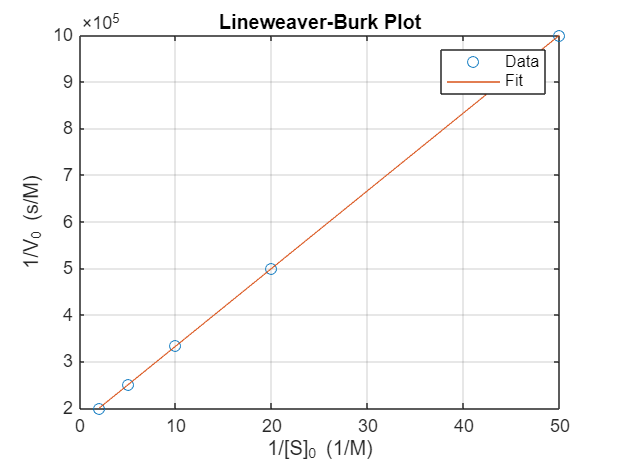


% Plotting Lineweaver-Burk Plot
figure;
plot(inverse_S0, inverse_V0, 'o');
hold on;
plot(inverse_S0, polyval(p, inverse_S0), '-');
xlabel('1/[S]_0 (1/M)');
ylabel('1/V_0 (s/M)');
title('Lineweaver-Burk Plot');
legend('Data', 'Fit');
grid on;

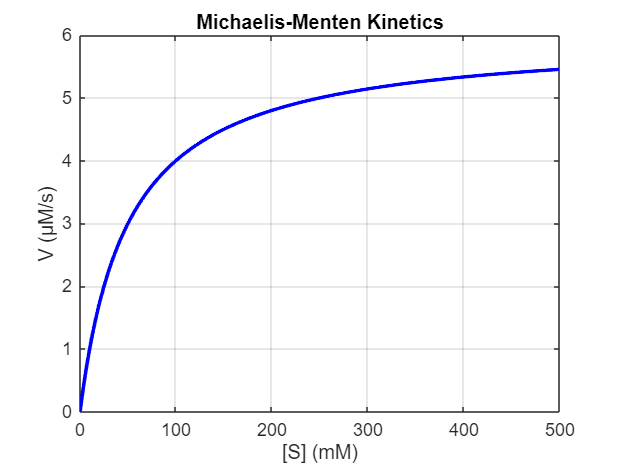

% Given parameters
Vmax = 6.0; % μM/s
Km = 50;    % mM (just an example value, you should use the calculated Km)

% Substrate concentration range
S = linspace(0, 500, 1000); % mM

% Michaelis-Menten equation
V = Vmax .* S ./ (Km + S);

% Plotting
figure;
plot(S, V, 'b', 'LineWidth', 2);
xlabel('[S] (mM)');
ylabel('V (μM/s)');
title('Michaelis-Menten Kinetics');
grid on;